# Partial derivatives and Tangent plane

## Introduction

The **essence** of calculus is the **derivative**. The **derivative** is the instantaneous rate of change of a function with respect to one of its variables. This is equivalent to finding the slope of the tangent line to the function at a point.

You already have learned some methods to calculate derivatives of functions and MATLAB can assist you to confirm your results or analyse the behaivour of the derivative graphically.

In this activity we will use the commands [`syms`](https://au.mathworks.com/help/symbolic/syms.html) and [`diff`](https://au.mathworks.com/help/symbolic/differentiation.html) to calculate partial derivatives symbolically.

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

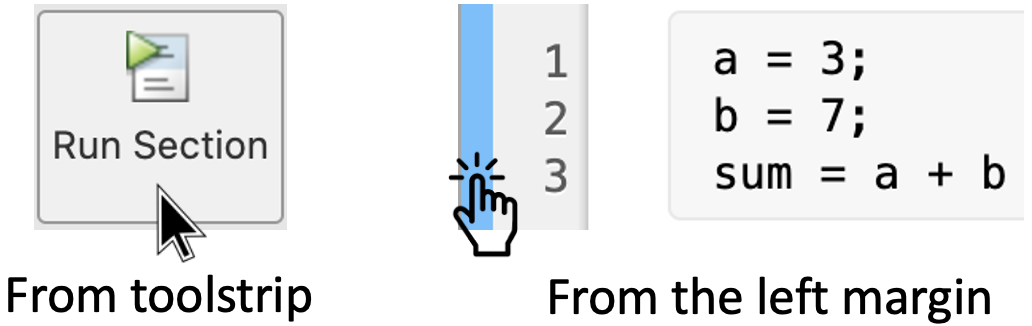

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. Symbolic calculation of derivatives and partial derivatives

### 1.1 One variable functions

To illustrate how to calculate derivatives of one variable functions in MATLAB, first we create a [symbolic expression](https://au.mathworks.com/help/symbolic/syms.html):

syms x            % Define the symbolic variable x
f = 1/(1 + x^2);  % Define the symbolic expression, i.e. f(x)

The command

diff(f)

differentiates "`f`" with respect to "`x`". Run this section to see the result.

### 1.2 Multivariate functions

If we wish to compute the partial derivatives of a multivariate function we must specify the variable. That is, [`diff(f, var)`](https://au.mathworks.com/help/symbolic/diff.html?searchHighlight=derivatives&s_tid=srchtitle_derivatives_2#btwp767-1). For example, consider the function:


$$f(x)=(x+y)\cos(x-y)$$


In order to compute $\frac{\partial f}{\partial x}$ and $\frac{\partial f}{\partial y}$ we write the code:

syms x y
f = (x + y) * cos(x - y);
partialX = diff(f, x)
partialY = diff(f, y)

Run this section to see the output. Compute the partial derivatives in your notebook to confirm the results.

### 1.3 Second order derivatives of multivariate functions

In MATLAB we can also easily compute second-order derivatives of multivariate functions with respect to a particular variable.

For example, consider the function


$$f(x)=(x+2y)^3$$


In order to compute the second order partial derivatives

$\frac{\partial^2f}{\partial x^2}$,  $\frac{\partial^2f}{\partial y^2}$,  $\frac{\partial^2f}{\partial x \partial y}$ and $\frac{\partial^2f}{\partial y \partial x}$, 

 we write the code:

syms x y
f = (x + 2*y)^3;
secPartialX = diff(f, x, 2)
secPartialY = diff(f, y, 2)
secPartialXY = diff(f, x, y)
secPartialYX = diff(f, y, x)

**Note 1:** The code `diff(f,x,2)` is equivalent to `diff(f,x,x)`. You can also compute higher-order derivatives. To learn more about it see: [Higher-order derivatives](https://au.mathworks.com/help/symbolic/diff.html#btwp91l-1).

## 2. Hands on practice

#### Activity 1: 

Compute all the second partial derivatives of the following functions:

- 
$$f_1(x,y) = \exp(xy)\sin (y)$$
 

- 
$$f_2(x,t) =\sqrt{3x+4t}$$


- 
$$f_3(x,y) = \frac{xy}{1+x^2+y^2}$$


- 
$$f_4(u,v) = \exp\left(-\frac{u^2+v^2}{3}\right)\big(\sin u^2 + \cos v^2\big)$$


Write your code here:

% Part 1:


% Part 2:


% Part 3:


% Part 4:



#### Activity 2:

The *van der Waals equation* for $n$ moles of a gas is


$$\left(P + \frac{n^2a}{V^2}\right) \left(V-nb\right) = nRT$$


where $P$ is the pressure, $V$ is the volume, and $T$ is the temperature of the gas. The constant $R$ is the universal gas constant and $a$ and $b$ are positive constants that are characteristic of a particular gas. Calculate 

$\frac{\partial T}{\partial P}$   and   $\frac{\partial P}{\partial V}$.

Write your code here:

% Partial of T with respect of P



% Partial of P with respect of V


